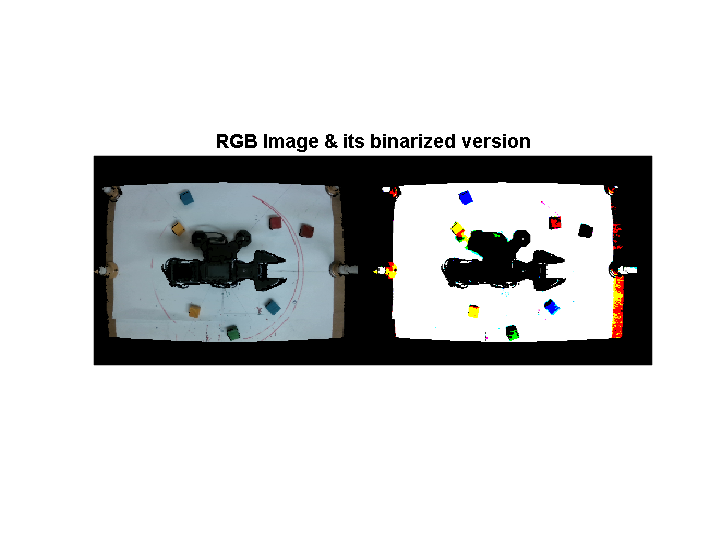

load rgb_im;
load depth_ig;

BW = imbinarize(im);
bin_img = BW;
figure;
imshowpair(im,BW,'montage');
title('RGB Image & its binarized version');

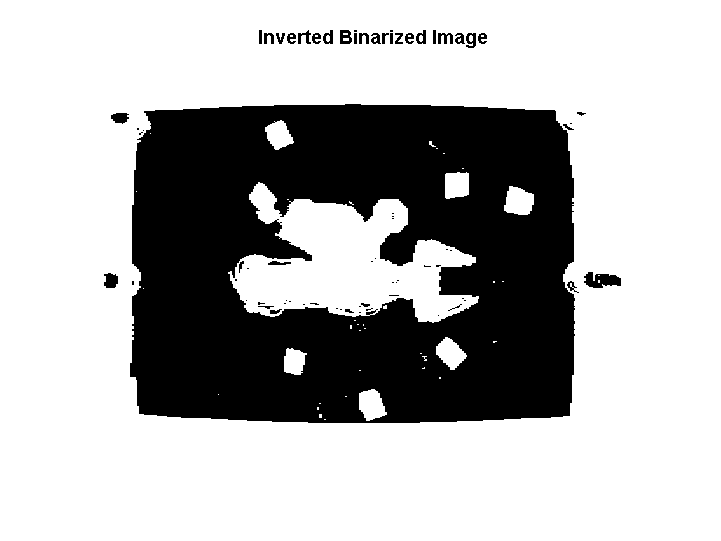

len = size(BW);

BW2 = ~(BW(:,:,1) & BW(:,:,2) & BW(:,:,3));
BW3 = BW2;
figure;
imshow(BW3);

title('Inverted Binarized Image');

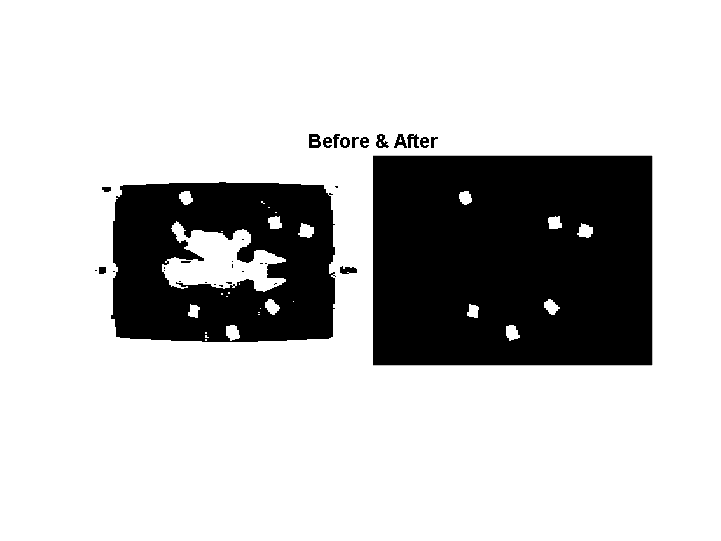

cc8 = bwconncomp(BW3);
remove_idx = [];

% here we filter out everyother thing except the cubes using 
% connected components that are too big or too small

for i = 1:length(cc8.PixelIdxList)
    if (length(cc8.PixelIdxList{i}) < 200) || (length(cc8.PixelIdxList{i}) > 2000)
        remove_idx(end + 1) = i;
    end
end

for i=1:length(remove_idx)
    BW2(cc8.PixelIdxList{remove_idx(i)}) = 0;
end


figure;
imshowpair(BW3, BW2, 'montage');
title('Before & After');

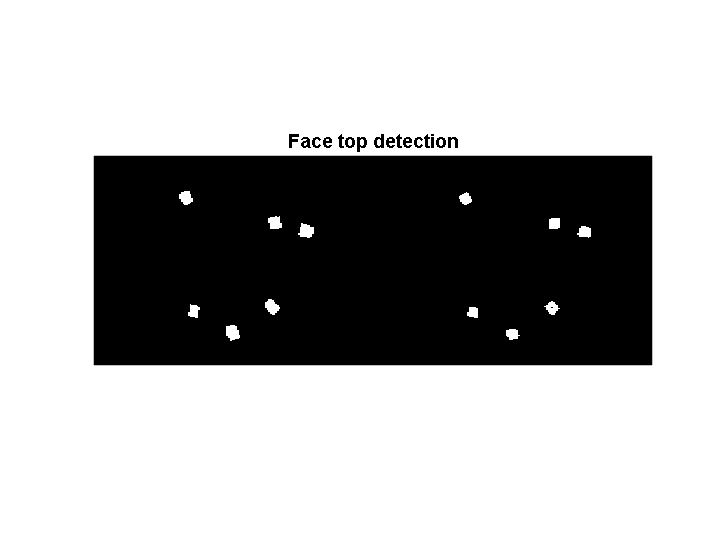

cc8 = bwconncomp(BW2); %function dettects on it own


BW4 = BW2;
object_info = struct;
object_info.Index_data = cc8.PixelIdxList; % Object Indices
object_info.rgb_image = im2double(im); % RGB Image
object_info.depth_info_cm = ig*100; % Depth Info in sm

object_info.red_val = zeros(1,length(object_info.Index_data)); % Avg Red for each obj

object_info.green_val = zeros(1,length(object_info.Index_data)); % Avg Green for each obj

object_info.blue_val = zeros(1,length(object_info.Index_data)); % Avg Blue for each obj

object_info.red_val_max = zeros(1,length(object_info.Index_data)); % Max Red for each obj

object_info.green_val_max = zeros(1,length(object_info.Index_data)); % Max Green for each obj

object_info.blue_val_max = zeros(1,length(object_info.Index_data)); % Max Blue for each obj


object_info.top_data = object_info.Index_data; % Indices for top faces of object
object_info.top_data_width = object_info.Index_data; % x Indices for top faces of object
object_info.top_data_column = object_info.Index_data; % y Indices for top faces of object
object_info.no_top_data = object_info.Index_data;
object_info.center_x = zeros(1, length(object_info.Index_data));
object_info.center_y = zeros(1, length(object_info.Index_data));
object_info.red_val_bin = zeros(1,length(object_info.Index_data));
object_info.green_val_bin = zeros(1,length(object_info.Index_data));
object_info.blue_val_bin = zeros(1,length(object_info.Index_data));

%top data extraction
for i = 1:length(object_info.Index_data)
    arr = [];
    for j = 1:length(object_info.Index_data{i}) %removing zero depth pixels
        if object_info.depth_info_cm(object_info.Index_data{i}(j)) ~= 0
            arr(end +1) = object_info.depth_info_cm(object_info.Index_data{i}(j));
        end
    end
    counts = hist(arr, 10);
    % figure;
    % histogram(arr,10);
    %start
    th = min(arr) + (otsuthresh(counts)*(max(arr) - min(arr)));
    r = 0;
    l = 0;
    for j = 1:length(object_info.Index_data{i}) 
        
        if object_info.depth_info_cm(object_info.Index_data{i}(j)) > th
            BW4(object_info.Index_data{i}(j)) = 0;
            object_info.top_data{i}(j-r) = [];
            r = r + 1;
        else
            object_info.no_top_data{i}(j-l) = [];
            l = l + 1;
        end
    end
end

for i = 1:length(object_info.top_data)
    object_info.top_data_column{i} = floor(object_info.top_data{i} ./ len(1)) + 1;
    object_info.top_data_width{i} = mod(object_info.top_data{i}, len(1));
    object_info.center_x(i) = floor(mean(object_info.top_data_width{i}));
    object_info.center_y(i) = floor(mean(object_info.top_data_column{i}));
    BW4(object_info.center_x(i), object_info.center_y(i)) = 0;
end


figure;
imshowpair(BW2, BW4, 'montage');
title('Face top detection');

avg_th = 0.2;
max_th = 0.3;
for k = 1:length(object_info.top_data_width)
    val_r = 0;
    val_g = 0;
    val_b = 0;
    max_r = -inf;
    max_g = -inf;
    max_b = -inf;
    for i = 1:length(object_info.top_data_width{k})
            if (object_info.rgb_image(object_info.top_data_width{k}(i),object_info.top_data_column{k}(i),1) > max_r)
                max_r = object_info.rgb_image(object_info.top_data_width{k}(i),object_info.top_data_column{k}(i),1);
            end
            if (object_info.rgb_image(object_info.top_data_width{k}(i),object_info.top_data_column{k}(i),2) > max_g)
                max_g = object_info.rgb_image(object_info.top_data_width{k}(i),object_info.top_data_column{k}(i),2);
            end
            if (object_info.rgb_image(object_info.top_data_width{k}(i),object_info.top_data_column{k}(i),3) > max_b)
                max_b = object_info.rgb_image(object_info.top_data_width{k}(i),object_info.top_data_column{k}(i),3);
            end
            val_r = val_r + object_info.rgb_image(object_info.top_data_width{k}(i),object_info.top_data_column{k}(i),1);
            val_g = val_g + object_info.rgb_image(object_info.top_data_width{k}(i),object_info.top_data_column{k}(i),2);
            val_b = val_b + object_info.rgb_image(object_info.top_data_width{k}(i),object_info.top_data_column{k}(i),3);
    end
    object_info.red_val(k) = val_r / length(object_info.top_data_width{k});
    object_info.green_val(k) = val_g / length(object_info.top_data_width{k});
    object_info.blue_val(k)= val_b / length(object_info.top_data_width{k});
    object_info.red_val_max(k) = max_r;
    object_info.green_val_max(k) = max_g;
    object_info.blue_val_max(k) = max_b;
    if object_info.red_val(k) >= 0.2 && object_info.red_val_max(k) > 0.30
        object_info.red_val_bin(k) = 1;
    end
    if object_info.green_val(k) >= 0.2 && object_info.green_val_max(k) > 0.30
        object_info.green_val_bin(k) = 1;
    end
    if object_info.blue_val(k) >= 0.2 && object_info.blue_val_max(k) > 0.30
        object_info.blue_val_bin(k) = 1;
    end
end
object_info

object_info = struct with fields:
         Index_data: {[740×1 double]  [631×1 double]  [833×1 double]  [798×1 double]  [768×1 double]  [871×1 double]}
          rgb_image: [480×640×3 double]
      depth_info_cm: [480×640 single]
            red_val: [0.0763 0.4753 0.1136 0.0939 0.2954 0.2021]
          green_val: [0.2501 0.3571 0.2709 0.2943 0.1300 0.0969]
           blue_val: [0.3368 0.1720 0.1842 0.3747 0.1349 0.0872]
        red_val_max: [0.3137 0.5529 0.3098 0.3137 0.4078 0.3098]
      green_val_max: [0.4667 0.4471 0.4392 0.4902 0.3216 0.2157]
       blue_val_max: [0.5373 0.3216 0.4471 0.5882 0.3529 0.2314]
           top_data: {[584×1 double]  [498×1 double]  [598×1 double]  [647×1 double]  [623×1 double]  [676×1 double]}
     top_data_width: {[584×1 double]  [498×1 double]  [598×1 double]  [647×1 double]  [623×1 double]  [676×1 double]}
    top_data_column: {[584×1 double]  [498×1 double]  [598×1 double]  [647×1 double]  [623×1 double]  [676×1 double]}
        no_top_data: {[156


pick_up_x = object_info.center_x(1)

pick_up_x = 98

pick_up_y = object_info.center_y(1)

pick_up_y = 213

input_to_lab7 = [pick_up_x,pick_up_y]

input_to_lab7 =     98   213
